clear; clc; addpath('utils\'); addpath('functions\'); [y,fs]=audioread('data/EQ2401Project2data2024.wav');
close all

**Notations**

    y       -   Noisy Speech Signal

    yhat    -   Estimated Sinusoidal Noise, e.g., yhat_lms is the noise estimated via LMS

    thetahat -  Filter Weights

    xhat    -   Estimated Denoised Speech

    delay   -   Delay in decorrelation stage

    step    -   Step Sizes for LMS / NLMS Filter Update

    lambda  -   Forgetting Factor for RLS

## LMS

%   Tunable Parameters
N_lms = 200;
delay_lms = 32;
step_lms = 0.02;

[~] = judgeStabilityLMS(y, N_lms, step_lms, 0); % Judge whether LMS is stable for given params

LMS is stable


tic;
[thetahatlms, xhatlms, yhatlms] = lms(y, N_lms, step_lms, delay_lms); 
t_lms = toc; 
disp(['Execution time of LMS  = ', num2str(t_lms), ' second(s)']);

Execution time of LMS  = 0.062868 second(s)


## NLMS

%   Tunable Parameters
N_nlms = 200;
delay_nlms = 32;
step_nlms = 0.2;
c_nlms = 1e-3; % c_nlms = 1; step_nlms = 0.2; very close to LMS

tic;
[thetahatnlms, xhatnlms, yhatnlms] = nlms(y, N_lms, step_nlms, c_nlms, delay_nlms);
t_nlms = toc; 
disp(['Execution time of NLMS = ', num2str(t_nlms), ' second(s)']);

Execution time of NLMS = 0.070861 second(s)


## RLS

%   Tunable Parameters
N_rls = 200;
delay_rls = 32;
lambda_rls = 1-1e-5;

tic;
[thetahatrls, xhatrls, yhatrls] = rls(y, N_rls, lambda_rls, delay_rls);
t_rls = toc; 
disp(['Execution time of RLS  = ', num2str(t_rls), ' second(s)']);

Execution time of RLS  = 4.6388 second(s)


## Plots

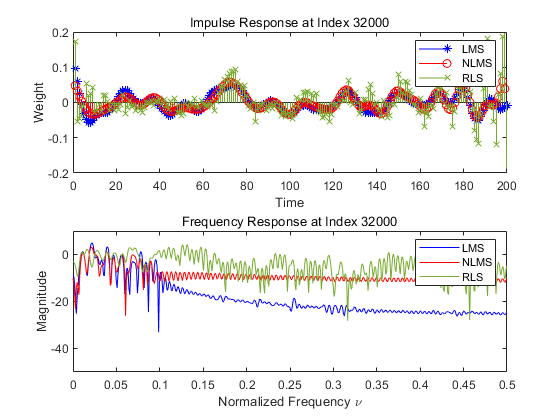

%   Dynamically plot the impulse and frequency responses of filters with respect to time
dynamicWeightResponsePlot(thetahatlms, thetahatnlms, thetahatrls,[1:10:200 200:200:length(y)-1])

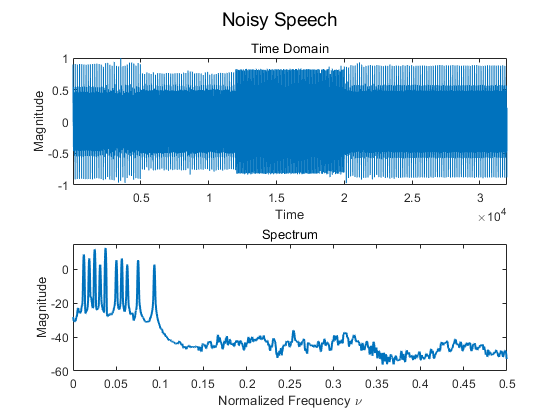

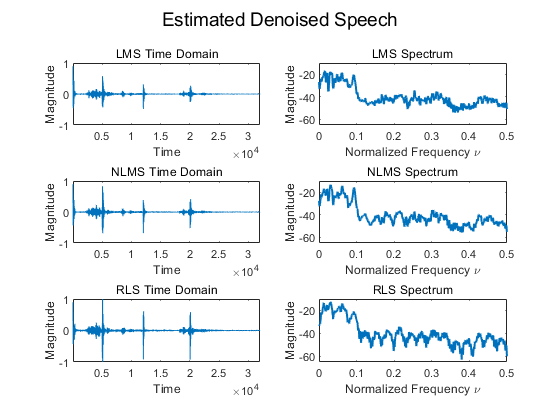

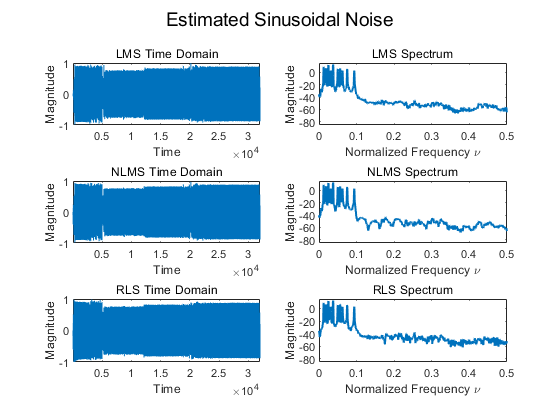

%   Plot the waveforms and spectrums of 1.original noisy signal 2.estimated sinusoidal noise 3.denoised speech
plotComp(y, xhatlms, xhatnlms, xhatrls, yhatlms, yhatnlms, yhatrls)

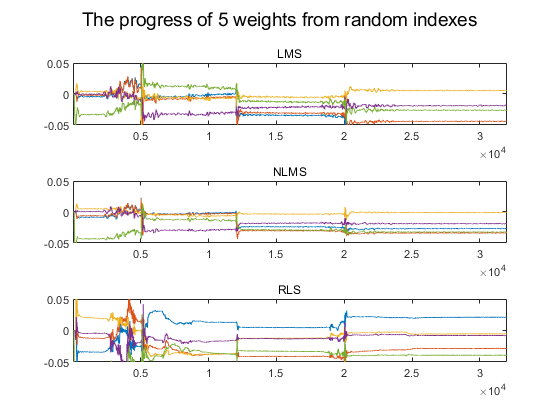

%   Randomly select 5 indexes, plot corresponding filter weights with respect to time
plotWeightProgress(thetahatlms, thetahatnlms, thetahatrls, 5)

## Play Sound, the order of sound: Original, LMS, NLMS, RLS

fprintf('Sequential order of what you hear:')

Sequential order of what you hear:

delta_t = length(y)/fs + 0.5;
fprintf('\n1. Original Noisy Speech')


1. Original Noisy Speech

soundsc(y, fs)
pause(delta_t)
fprintf('\n2. LMS')


2. LMS

soundsc(xhatlms, fs)
pause(delta_t)
fprintf('\n3. NLMS')


3. NLMS

soundsc(xhatnlms, fs)
pause(delta_t)
fprintf('\n4. RLS\n')


4. RLS


soundsc(xhatrls, fs)
pause(delta_t)

## Extras, using other LMS-related Algorithms from the Last Lecture

%   Do not run this section if you only want to see lms, nlms, and rls
pause(2)
run extras.m

Now executing other LMS-related algorthims
Sequential order of what you hear:
1. LMS (as a reference)
2. Leaky LMS
3. Sign Error
4. Sign Regressor
5. Sign Sign
6. LMS Volterra
7. Momentum LMS
